# Tutorial on Global Sensitivity Analyses

Christina Lee (Fall 2023)

**Contents:**

- Uncertainty Analyses

- Global Sensitivity Metrics

**Background:**

While local (one at a time) sensitivity analyses are useful and intuitive, they can be misleading - particularly if there is a lot of uncertainty in the "base" parameters in your model. Often model behavior is can be specific to specific parameter values, and results on local sensitivity analyses can be quite different when those base parameter values change.

Thus, global uncertainty and sensitivity analyses aim to combat this challenge. These methodologies typically will use quasi-monte carlo sampling to create near-random parameter sets given parameter distributions or bounds. Two of the most common are Latin Hypercube Sampling (LHS) and Sobol Sequences.

In our lab, we have only used LHS - but Sobol Sensitivity Analyses is possible.

### **Model Example:**

A simple Ligand-Receptor binding model witth six parameters and two reactions:

- L+R<->LR (Ligind binding receptor)

- LR<->LRp (Phosphorylation of Ligand:Receptor Complex)

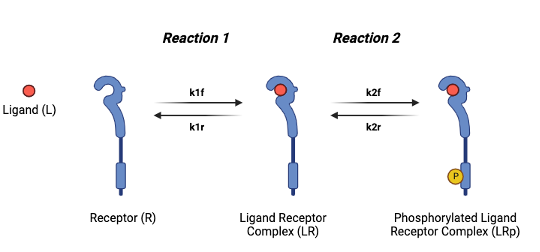

%% define parameters
k1f = 1;    % [uM^-1 s^-1] react1 forward rate constant
k1r = 1;    % [s^-1] react1 reverse rate constant
k2f = 0.1;    % [uM^-1 s^-1] react2 forward rate constant
k2r = 0.05;    % [s^-1] react2 reverse rate constant
L = 1;   % [uM] concentration of ligand
Rtot = 1;   % [uM] total concentration of receptor
params = {k1f,k1r,k2f,k2r,L,Rtot}; % collect parameters
param_names = ["k1f", "k1r", "k2f", "k2r","L","Rtot"]; % parameter names

## Latin Hypercube Sampling

The framework that the Kirschner Group uses has a bit of the LHS framework hidden. Below is how to complete LHS using built-in MATLAB functions: [`lhsdesign`](https://www.mathworks.com/help/stats/lhsdesign.html) and [`icdf`](https://www.mathworks.com/help/stats/prob.normaldistribution.icdf.html).

Through this tutorial, you will get intuition on how LHS works and how flexible it can be.

### Create a Unit LHS Matrix:

rng default % for reproducibilitty
num_params = length(params); % 6 parameters
num_samples = 10000; % 10000 samples
LHSmat = lhsdesign(num_samples,num_params); % Create a unit LHS (values between 0 and 1)

### Convert Unit LHS Matrix to Desired Distributions:

MATLAB's built-in function creates a unit LHS Matrix, meaning values are selected between 0 and 1 for each column.

Now we want to define the actual parameter probability distribution for each parameter. This can be done using the inverse CDF function as shown below for each parameter:

- Normal Distribution (mean = 1, std = 0.1)

- Log Normal Distribtion (mean = log(2), std = 1) Note: *this is a common distribution used in PK/PD and QSP modeling*

- Uniform Distribtion (min = 0.01, max = 10) *we commonly use the uniform or log uniform distribtion*

- Log Uniform Distribtion (min = 0.01, max = 100)

- Exponential Distribition (mean = 5) *just for fun to show there are a lot of distributions that can be used*

- Half Normal

% Now Convert to Desired Distributions
Final_LHSmat = LHSmat;

% Let's sat parameter 1 has a Normal Distribution with:
mu = 1; % mean of 1
sigma = 0.1; % sigma of 0.05
Final_LHSmat(:,1) = icdf('Normal',LHSmat(:,1),mu,sigma);

% Parameter 2 has a Log Normal
mu = log(2); % mean of log(2)
sigma = 1; % sigma of 1
pd = makedist('LogNormal','mu',mu,'sigma',sigma);
Final_LHSmat(:,2) = icdf(pd,LHSmat(:,2));

% Parameter 3 has a Uniform Distribution
lb = 0.01;
ub = 10;
pd = makedist('Uniform','lower',lb,'upper',ub);
Final_LHSmat(:,3) = icdf(pd,LHSmat(:,3));

% Parameter 4 has a Log Uniform Distribution
lb = 0.01;
ub = 100;
pd = makedist('Loguniform','lower',lb,'upper',ub);
Final_LHSmat(:,4) = icdf(pd,LHSmat(:,4));

% Parameter 5 has an Exponential Distribution
mu = 5;
pd = makedist('Exponential',mu);
Final_LHSmat(:,5) = icdf(pd,LHSmat(:,5));

% Parameter 6 has a Half-Normal Distribution
mu = 10;
sigma = 5;
pd = makedist('HalfNormal','mu',mu,'sigma',sigma);
Final_LHSmat(:,6) = icdf(pd,LHSmat(:,6));

**Plot to Observe the Distributions**

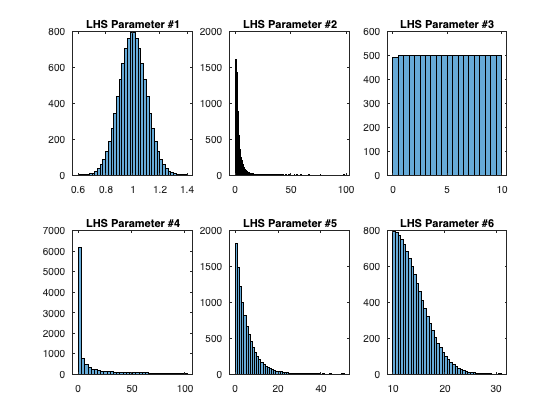

figure
for i = 1:size(LHSmat,2)
    subplot(2,3,i)
    histogram(Final_LHSmat(:,i))
    title(strcat("LHS Parameter #", num2str(i)))
end

## Sobol Sequences

Sobol sequences are another method to create quasi-random sampling of mullti-dimensional parameter spaces. Similar to the LHS framework, setting up the Sobol Sequence requires transformation from the unit sampling framework to your desired probability distribution.

p = sobolset(num_params); % generate the sobol sequence
p = scramble(p,'MatousekAffineOwen');
SOBOLmat = net(p,num_samples); % create matrix (similar to LHSmat)

% Now Convert to Desired Distributions
Final_SOBOLmat = SOBOLmat;

% Let's sat parameter 1 has a Normal Distribution with:
mu = 1; % mean of 1
sigma = 0.1; % sigma of 0.05
Final_SOBOLmat(:,1) = icdf('Normal',SOBOLmat(:,1),mu,sigma);

% Parameter 2 has a Log Normal
mu = log(2); % mean of log(2)
sigma = 1; % sigma of 1
pd = makedist('LogNormal','mu',mu,'sigma',sigma);
Final_SOBOLmat(:,2) = icdf(pd,SOBOLmat(:,2));

% Parameter 3 has a Uniform Distribution
lb = 0.01;
ub = 10;
pd = makedist('Uniform','lower',lb,'upper',ub);
Final_SOBOLmat(:,3) = icdf(pd,SOBOLmat(:,3));

% Parameter 4 has a Log Uniform Distribution
lb = 0.01;
ub = 100;
pd = makedist('Loguniform','lower',lb,'upper',ub);
Final_SOBOLmat(:,4) = icdf(pd,SOBOLmat(:,4));

% Parameter 5 has an Exponential Distribution
mu = 5;
pd = makedist('Exponential',mu);
Final_SOBOLmat(:,5) = icdf(pd,SOBOLmat(:,5));

% Parameter 6 has a Half-Normal Distribution
mu = 10;
sigma = 5;
pd = makedist('HalfNormal','mu',mu,'sigma',sigma);
Final_SOBOLmat(:,6) = icdf(pd,SOBOLmat(:,6));

**Plot to Observe the Distributions**

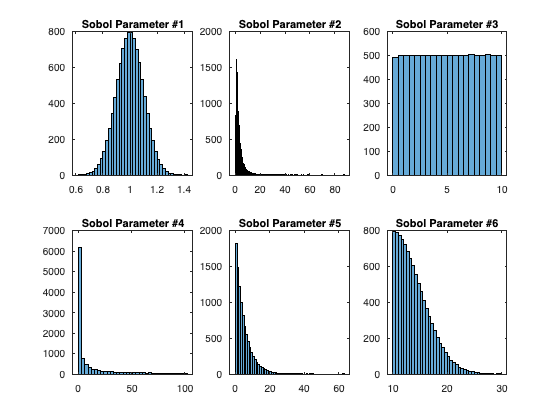

figure
for i = 1:size(SOBOLmat,2)
    subplot(2,3,i)
    histogram(Final_SOBOLmat(:,i))
    title(strcat("Sobol Parameter #", num2str(i)))
end

## Uncertainty Metrics

Latin hypercube sampling is normally paired with a sensitivity metric called the Partial Rank Correlation Coefficient (**PRCC**). The PRCC is a multivate version of correlation coefficient that uses the rank order information of the parameters with the output of interest to calculate a correlation coefficient. The main drawback of this approach is that it requires the relationship to be monotonic (either increasing or decreasing, never both over the parameter range).

Sobol Sequences are used to calculate **sobol indices**. These indices have a basis similar to ANOVA tests and can be used on non-linear and non-monotonic relations.

### LHS-PRCC Analysis

Let's now do the LHS-PRCC analysis using the simple model and our generated LHS matrix.

% Run the Model for each parameter set in the LHSmatrix
% and collect desired outputs.
LRfinal = zeros(num_samples,1); % collect output for LR complex formation
LRpfinal = zeros(num_samples,1); % collect output for LRp
y0 = [0,0]; % initial conditions
options = []; % ODE solver options
tspan = [0 60]; % time span of simulation
for params_idx = 1:num_samples
    global_params = num2cell(Final_LHSmat(params_idx,:)); % pull the parameter set for sample "N"
    [t,y] = ode15s(@ODEfunc,tspan,y0,options,global_params); % call the ODE solver
    LRfinal(params_idx) = y(end,1); % save output for [LR]
    LRpfinal(params_idx) = y(end,2); % save output for [LRp]
end

**Calculate the PRCC**

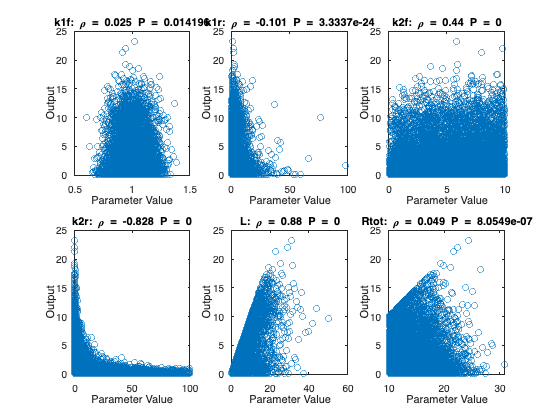

y = LRpfinal; % Define your output of Interest

figure
param_rhos = zeros(num_params,1); % PRCC for each parameter
param_pvals = zeros(num_params,1); % Pval for each parameter's rho
pcc_ztest = zeros(num_params,1); % Z-test 
pcc_ztest_signif = zeros(num_params,1); % PCC z-test p-value
for p_idx = 1:num_params
    x = Final_LHSmat(:,p_idx); % look at each parameter
    z = Final_LHSmat;
    z(:,p_idx) = []; % control for all other parameters
    [rho,pval] = partialcorr(x,y,z,'Type','Spearman'); % calculate the PRCC
    param_rhos(p_idx) = rho;
    param_pvals(p_idx) = pval;

    % Visualize Results:
    subplot(2,3,p_idx)
    plot(x,y,'o')
    xlabel('Parameter Value')
    ylabel('Output')
    title(strcat(param_names(p_idx), ": \rho = ", num2str(round(rho,3)), ...
        " P = ", num2str(pval)))

    % Calculate Z-test which needs PCC, not PRCC. (Determines if rho is
    % significantly different from zero.
    [rho, ~] = partialcorr(x, y, z);
    % Equation 8 in doi:10.1016/j.jtbi.2008.04.011
    fisher_transform = @(r) 0.5 * log(abs((1 + r) ./ (1 - r)));
    % Equation 10 in doi:10.1016/j.jtbi.2008.04.011
    [h, p] = ztest(fisher_transform(rho), 0, 1);
    pcc_ztest(p_idx) = h;
    pcc_ztest_signif(p_idx) = p;

end

**Visualize Results**

Results are often plotted as a bar chart. P-values can be reported for the PRCC or using the z-test method.

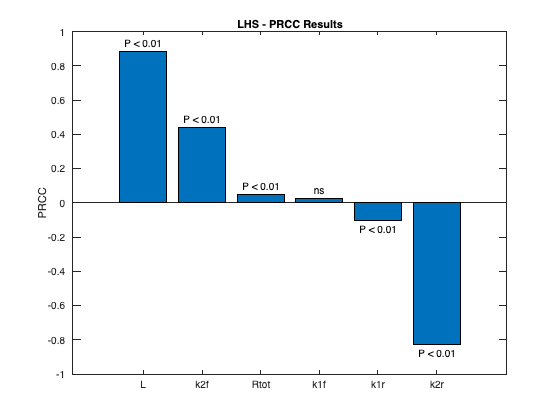

figure
[~, sorted_idx] = sort(param_rhos,'descend'); % sort PRCC values
bar(param_rhos(sorted_idx))
xticklabels(param_names(sorted_idx))
ylabel("PRCC")
title("LHS - PRCC Results")

% plot significance (from PRCC)
alpha = 0.01; % significance level
for i = 1:length(param_rhos)
    if param_pvals(sorted_idx(i)) < alpha
        sig_str = strcat("P < ", num2str(alpha));
    else
        sig_str = "ns";
    end
    text(i,param_rhos(sorted_idx(i)) + sign(param_rhos(sorted_idx(i)))*0.05,sig_str,...
        'HorizontalAlignment', 'center')
end

### Sobol Indices

Sobol indices require a lot of additional steps to calculate the sensitivity metrics (commonly first order and total order indices). There are some publicly avaible methods to be able to calculate these indices. While I won't go through this stepwise, below is code that uses a publicly available package to run Sobol and FAST (requires functions in GSAT folder, **make sure to add to path**).

Additionally, we will need to create a script that handles the ODE model in a format that can be used by this package. See the "Sobol_ODEfunc.m" script for details.

**Initialize Model in GSAT Format**

pro = pro_Create(); % create structure for model.

% add to the project 6 input variables, distributed in the 
% range [0 1] and indicate that the variables will be sampled following a 
% Sobol set (it will be harder to use Sobol sequences with distributions
% like above - but typically uniform Sobol is used anyways).
pro = pro_AddInput(pro, @()pdf_Sobol([0 1]), 'k1f');
pro = pro_AddInput(pro, @()pdf_Sobol([0 1]), 'k1r');
pro = pro_AddInput(pro, @()pdf_Sobol([0 1]), 'k2f');
pro = pro_AddInput(pro, @()pdf_Sobol([0 1]), 'k2r');
pro = pro_AddInput(pro, @()pdf_Sobol([0 1]), 'Ltot');
pro = pro_AddInput(pro, @()pdf_Sobol([0 1]), 'Rtot');

% set the model, ODE simulation variables, and name it as 'model', to the project 
y0 = [0,0]; % initial conditions
options = []; % ODE solver options
tspan = [0 60]; % time span
yout_idx = 2; % ODE index for desired model output
pro = pro_SetModel(pro, @(x)Sobol_ODEfunc(x,tspan,y0,options,yout_idx), 'model');

% set the number of samples for the quasi-random Monte Carlo simulation
pro.N = num_samples; % continue increasing this value until results are stable

% initialize the project by calculating the model at the sample points
pro = GSA_Init(pro);

**Calculate the Sensitivity Metrics**

The sensitivity metrics include a total order index and first order index for each parameter that was varied.

**Note:** this portion of thee code can take a long time to run.

% Get Total and First Order Indices for Each Parameter:
Stot_by_param = zeros(1,length(pro.Inputs.Names));
S1_by_param = zeros(1,length(pro.Inputs.Names));
eStot_by_param = zeros(1,length(pro.Inputs.Names));
eS1_by_param = zeros(1,length(pro.Inputs.Names));

for i = 1:length(pro.Inputs.Names)
    
    % Total Order Indices
    [Stot, eStot, pro] = GSA_GetTotalSy(pro, {i});

    % First Order Indices
    [S, eS, pro] = GSA_GetSy(pro, {i});

    Stot_by_param(i) = Stot; % save total indices for each parameter
    S1_by_param(i) = S; % save first order indices for each parameter

    eStot_by_param(i) = eStot; % error for total indices
    eS1_by_param(i) = eS; % error for first order indices
end

**Visualize the Results**

Create a stacked bar chart that includes the first order indices a fraction of the total order index for each parameter.

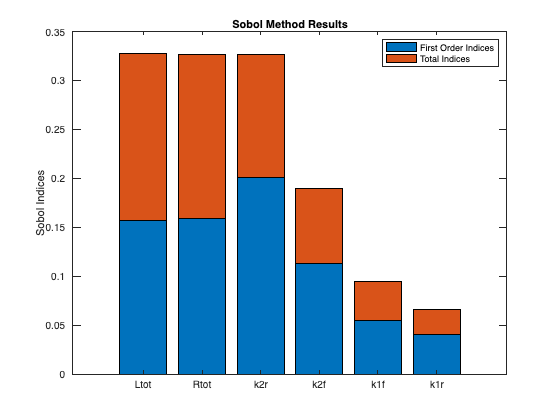

[~,sorted_idx] = sort(Stot_by_param,'descend'); % sort by most significant to least

figure
Stot_addS1 = Stot_by_param - S1_by_param; % format for stacked bar (S1 is a portion of Stot)
data = [S1_by_param;Stot_addS1]';
bar(data(sorted_idx,:),'stacked')
xticklabels(pro.Inputs.Names(sorted_idx))
legend({'First Order Indices','Total Indices'})
ylabel('Sobol Indices')
title('Sobol Method Results')